# WEEK 2 QUIZ 2

#### Question 1

To complete this quiz you need to import two files:

- The flights data for January 2015, "flightsJAN.csv" using the importFlightsData function

- The "airports.csv" containing the airport data

To import these files, use the code below. The option "TextType" in the READTABLE function forces textual data in the file to be read in as the string data type. The AIRPORT variable is then converted to a categorical variable, which is necessary for join operations used later.

- `flights = importFlightsData("flightsJan.csv");`

- `airports = readtable("airports.csv", "TextType``", "string");`

- `airports.AIRPORT`` = categorical(airports.``AIRPORT``);`

The table of airports has the variable "DISPLAY_AIRPORT_CITY_NAME_FULL". This is a list of strings containing the name of the city and the state/territory for each airport. For instance, LAX is in "Los Angeles, CA", and Ponce Airport is in "Ponce, Puerto Rico". Use this variable to generate an array of just the state/territory for each airport. For example: PA, TX, NM, SD...   

How many unique states/territories are there in the list of airports?

flights = importFlightsData("flightsJan.csv");
airports = readtable("airports.csv", "TextType", "string");
airports.AIRPORT = categorical(airports.AIRPORT)

airports = 322×5 table
    AIRPORT           DISPLAY_AIRPORT_NAME             DISPLAY_AIRPORT_CITY_NAME_FULL     LATITUDE    LONGITUDE
    _______    ___________________________________    ________________________________    ________    _________

      ABE      "Lehigh Valley International"          "Allentown/Bethlehem/Easton, PA"     40.655      -75.438 
      ABI      "Abilene Regional"                     "Abilene, TX"                        32.409       -99.68 
      ABQ      "Albuquerque International Sunport"    "Albuquerque, NM"                    35.042      -106.61 
      ABR      "Aberdeen Regional"                    "Aberdeen, SD"                        45.45      -98.422 
      ABY      "Southwest Georgia Regional"           "Albany, GA"                         31.532      -84.196 
      ACT      "Waco R

StateTerritory = extractAfter(airports.DISPLAY_AIRPORT_CITY_NAME_FULL,", ")

StateTerritory = 322×1 string array
    "PA"
    "TX"
    "NM"
    "SD"
    "GA"
    "TX"
    "CA"
    "NJ"
    "AK"
    "AK"
    "LA"
    "GA"
    "NY"
    "IA"
    "TX"
    "AK"
    "MI"
    "CO"
    "GA"
    "WI"
    "TX"
    "NC"
    "PA"
    "MI"
    "CT"
    "AK"
    "CA"
    "AL"
    "MT"
    "ND"


airports.StateTerritory2 = split(airports.DISPLAY_AIRPORT_CITY_NAME_FULL,", ")

airports = 322×6 table
    AIRPORT           DISPLAY_AIRPORT_NAME             DISPLAY_AIRPORT_CITY_NAME_FULL     LATITUDE    LONGITUDE              StateTerritory2           
    _______    ___________________________________    ________________________________    ________    _________    ____________________________________

      ABE      "Lehigh Valley International"          "Allentown/Bethlehem/Easton, PA"     40.655      -75.438     "Allentown/Bethlehem/Easton"    "PA"
      ABI      "Abilene Regional"                     "Abilene, TX"                        32.409       -99.68     "Abilene"                       "TX"
      ABQ      "Albuquerque International Sunport"    "Albuquerque, NM"                    35.042      -106.61     "Albuquerque"                   "NM"
      ABR   

airports = splitvars(airports,"StateTerritory2","NewVariableNames",["Territory" , "State"])

airports = 322×7 table
    AIRPORT           DISPLAY_AIRPORT_NAME             DISPLAY_AIRPORT_CITY_NAME_FULL     LATITUDE    LONGITUDE             Territory              State
    _______    ___________________________________    ________________________________    ________    _________    ____________________________    _____

      ABE      "Lehigh Valley International"          "Allentown/Bethlehem/Easton, PA"     40.655      -75.438     "Allentown/Bethlehem/Easton"    "PA" 
      ABI      "Abilene Regional"                     "Abilene, TX"                        32.409       -99.68     "Abilene"                       "TX" 
      ABQ      "Albuquerque International Sunport"    "Albuquerque, NM"                    35.042      -106.61     "Albuquerqu

size(unique(StateTerritory),1)

ans = 55

#### Question 2

Add the array of states/territories for each airport to your existing table of airports as a new variable. 

Then sort the updated airport table using two criteria (in ascending order):

- by the new state/territory variable

- by the 3-letter code in the "AIRPORT" variable (for states with multiple airports).

What are the first 3 airports in your new sorted table?

- ABE, ABI, ABQ

- ADK, ADQ, AKN

- ADK, ADQ, ANC

- ABR, ABI, ADK

- AAD, AAP, ABA

airports_full=[airports,table(StateTerritory)]

airports_full = 322×6 table
    AIRPORT           DISPLAY_AIRPORT_NAME             DISPLAY_AIRPORT_CITY_NAME_FULL     LATITUDE    LONGITUDE    StateTerritory
    _______    ___________________________________    ________________________________    ________    _________    ______________

      ABE      "Lehigh Valley International"          "Allentown/Bethlehem/Easton, PA"     40.655      -75.438          "PA"     
      ABI      "Abilene Regional"                     "Abilene, TX"                        32.409       -99.68          "TX"     
      ABQ      "Albuquerque International Sunport"    "Albuquerque, NM"                    35.042      -106.61          "NM"     
      ABR      "Aberdeen Regional"                    "Aberdeen, SD"                        45.45      -98.422       

airports_full=movevars(airports_full,'StateTerritory','After','DISPLAY_AIRPORT_CITY_NAME_FULL')

airports_full = 322×6 table
    AIRPORT           DISPLAY_AIRPORT_NAME             DISPLAY_AIRPORT_CITY_NAME_FULL     StateTerritory    LATITUDE    LONGITUDE
    _______    ___________________________________    ________________________________    ______________    ________    _________

      ABE      "Lehigh Valley International"          "Allentown/Bethlehem/Easton, PA"         "PA"          40.655      -75.438 
      ABI      "Abilene Regional"                     "Abilene, TX"                            "TX"          32.409       -99.68 
      ABQ      "Albuquerque International Sunport"    "Albuquerque, NM"                        "NM"          35.042      -106.61 
      ABR      "Aberdeen Regional"                    "Aberdeen, SD"                           "SD"           45.45  

airports_full = sortrows(airports_full,["StateTerritory","AIRPORT"'],["ascend","ascend"]);
%airports_full = sortrows(airports_full,'AIRPORT')
airports_full.AIRPORT(1:3)

ans = 3×1 categorical array
     ADK 
     ADQ 
     AKN 


#### Question 3

Imagine you have two tables of data that you would like to combine using one of the joining operations in the Joining Tables Live Task. 

On the left is a table containing demographic data for all countries in Europe, and on the right is a table containing economic data for all countries in the world with populations greater than 20 million. 

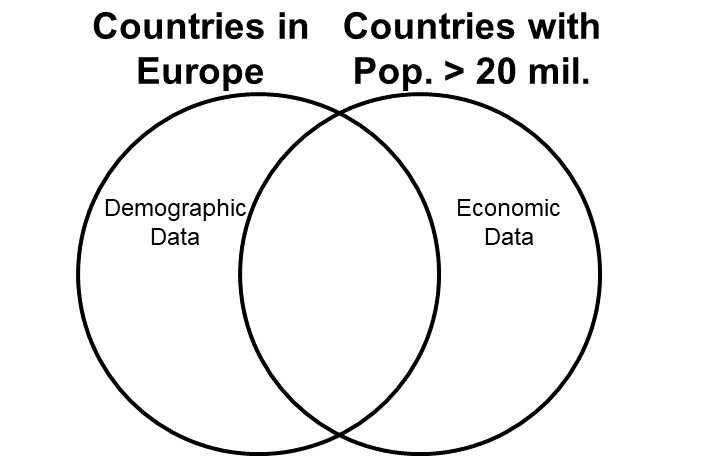

Which Joining method would result in a table that contains both demographic and economic data for only European countries with populations greater than 20 million?  

Hint: use the visuals in the Live Task and shown in the [Joining Tables video](https://www.coursera.org/learn/feature-engineering-matlab/lecture/3T8YH/joining-tables) to help you identify the correct joining method. 

- Right Outer Join

- Outer Join

- Left Outer Join

- Join

- Inner Join

disp("Inner Join")

T = 469978×26 table
    AIRPORT_ORIGIN        DISPLAY_AIRPORT_NAME          DISPLAY_AIRPORT_CITY_NAME_FULL     StateTerritory    LATITUDE    LONGITUDE              AIRLINE              TAIL_NUMBER    FLIGHT_NUMBER    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    REAL_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    ______________<

#### Question 4

Use the JOIN function to merge the flights and airports tables using ORIGIN and AIRPORT as key variables respectively. What three states/territories have the least number of flights in January?

- American Samoa, DE, Guam

- American Samoa, Guam, Puerto Rico

- TX, CA, FL

- AK, AL, AR

- DE, WV, SD

T= outerjoin(airports_full,flights,"LeftKeys","AIRPORT","RightKeys","ORIGIN","MergeKeys",true)
TT=sortrows(groupsummary(T,"StateTerritory"),'GroupCount');

ans = 3×1 table
     StateTerritory 
    ________________

    "American Samoa"
    "DE"            
    "Guam"          


TT(1:3,1)

#### Question 5

The times reported in the flights table are the local times for the origin and destination airports. This means you can tell if a flight changes time zones by comparing the variable "SCHEDULED_ELAPSED_TIME" with the difference between the variables "SCHEDULED_ARRIVAL_TIME" and "SCHEDULED_DEPARTURE_TIME". If a flight traveled from one time zone to another, then the difference between the arrival and departure times IS different than the elapsed time. 

What percentage (from 0 to 100) of the flights from the January data change time zones? 

**Hint: **The SCHEDULED_ELAPSED_TIME is a numeric variable. After subtracting two datetimes you will have a duration variable. One of them will need to be converted before comparing if the contents are equal.

flights.REAL_ELAPSED_TIME = flights.SCHEDULED_ARRIVAL_TIME - flights.SCHEDULED_DEPARTURE_TIME;
flights.REAL_ELAPSED_TIME =minutes(flights.REAL_ELAPSED_TIME);
flights=movevars(flights,'REAL_ELAPSED_TIME','After','SCHEDULED_ELAPSED_TIME')

flights = 469968×21 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    REAL_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    ________________

TIME_DIFFERENCE = flights(flights.SCHEDULED_ELAPSED_TIME == flights.REAL_ELAPSED_TIME,:)

TIME_DIFFERENCE = 242469×21 table
              AIRLINE              TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    REAL_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    ___________________________    ___________    _____________    ______    ___________    ________________________

(size(flights,1)-size(TIME_DIFFERENCE,1))/size(flights,1)

ans = 0.4841

Question 6

Imagine that 3 new airports are going to open this year. You have the relevant information for these new airports stored in their own table seen below.   

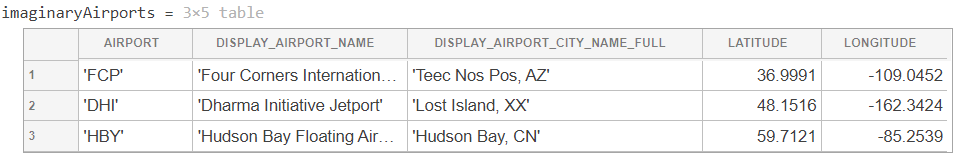

What is the correct method to combine this new table with your original table of airports?

- Horizontal Concatenation

- Inner Join

- Vertical Concatenation

- Left Outer Join

- Right Outer Join

disp('Vertical Concatenation')

Question 7

Assume you have imported the following table containing the time of all the total solar eclipses in the USA since 1970.

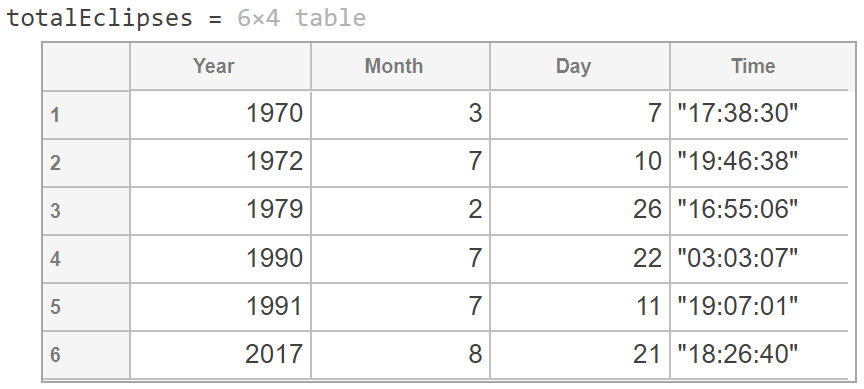

Which code would correctly convert this data into a list of datetimes? Select all that apply.

- `datetimeEclipses = datetime(totalEclipses.Year, totalEclipses.Month, totalEclipses.Day);`

- `datetimeEclipses = datetimeEclipses + duration(totalEclipses.Time)`

- `datetimeEclipses = datetime(totalEclipses.Day``, totalEclipses.``Month``, totalEclipses.``Year``);`

- `datetimeEclipses = datetimeEclipses + duration(totalEclipses.``Ti `

- `datetimeString = string(totalEclipses.Year) + "-" + string(totalEclipses.Month) + "-" + string(totalEclipses.Day) + " " + totalEclipses.Time;`

- `datetimeEclipses = datetime(datetimeString,"InputFormat","yyyy-MM-dd HH:mm:ss")`

- `datetimeString = string(totalEclipses.Year) + "-" + string(totalEclipses.``Month``) + "-" + string(totalEclipses.``Day``) + " " + totalEclipses.``Time``;`

- `datetimeEclipses = datetime(datetimeString,"InputFormat``","dd-``MM``-yyyy ``HH``:mm:ss")`